# J1リーグ引き分け数の集計

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む

tbl_result=readtable('../data/JLeagueResults.xlsx');
tbl_result.Category=categorical(tbl_result.Category);
tbl_result=tbl_result(tbl_result.Year>=2014,:);
yearVals=unique(tbl_result.Year);
numResults=zeros(10,3,3);

年，リーグごとにホームの勝ち・引き分け・負け数を集計

for yearVal=yearVals'
    indYear=find(yearVal==yearVals);
    for divisionNum=1:3
        switch divisionNum
            case 1
                ind = tbl_result.Year==yearVal ...
                    & (tbl_result.Category=='Ｊ１' ...
                    | tbl_result.Category=='Ｊ１ １ｓｔ' ...
                    | tbl_result.Category=='Ｊ１ ２ｎｄ');
            case 2
                ind = tbl_result.Year==yearVal ...
                    & tbl_result.Category=='Ｊ２';
            case 3
                ind = tbl_result.Year==yearVal ...
                    & tbl_result.Category=='Ｊ３';
        end

        tbl_tmp=tbl_result(ind,:);
        numWins=sum(tbl_tmp.HomeGoals>tbl_tmp.AwayGoals);
        numDraws=sum(tbl_tmp.HomeGoals==tbl_tmp.AwayGoals);
        numLoses=sum(tbl_tmp.HomeGoals<tbl_tmp.AwayGoals);

        numResults(indYear, :,divisionNum)=[numWins numDraws numLoses];
    end
end

図示

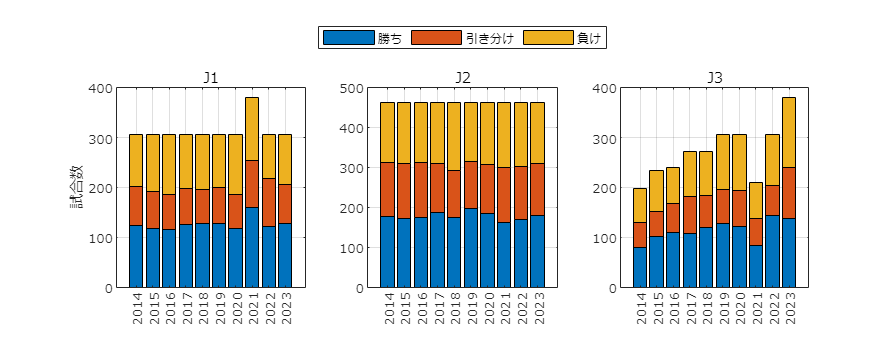

figure
set(gcf,'Position',[320 1000 350*3 400]);
tiledlayout(1,3);
for divisionNum=1:3
    nexttile;
    bar(numResults(:,:,divisionNum),'stacked');
    set(gca,'fontname','メイリオ');
    grid on;
    xticklabels(yearVals);
    title(['J' num2str(divisionNum)],'FontName','メイリオ')
    if divisionNum==1
        ylabel('試合数')
    end
    if divisionNum==2
        legend({'勝ち','引き分け','負け'},'Location','northoutside','Orientation','horizontal')
    end
end
exportgraphics(gcf,'fig_numWDLinJLeague.pdf');

figure;

tiledlayout(1,2);
set(gcf,'Position',[320 1000 400*2 400]);
nexttile;hold on;grid on;set(gca,'fontname','メイリオ');
lineStyleStr={'-','--',':'}

lineStyleStr = 1×3 の cell 配列
    {'-'}    {'--'}    {':'}


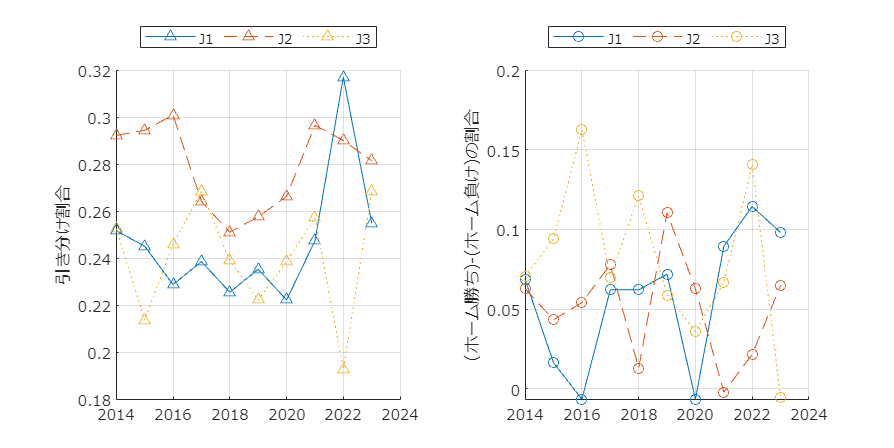

for divisionNum=1:3
    plotY=numResults(:,2,divisionNum)./sum(numResults(:,:,divisionNum),2);
    plot(yearVals,plotY,['^' lineStyleStr{divisionNum}])
end
ylabel('引き分け割合');
legend({'J1','J2','J3'},'Location','northoutside','Orientation','horizontal')

nexttile;hold on;grid on;set(gca,'fontname','メイリオ');
for divisionNum=1:3
    plotY=(numResults(:,1,divisionNum)- numResults(:,3,divisionNum)) ...
        ./sum(numResults(:,:,divisionNum),2);
    plot(yearVals,plotY,['o' lineStyleStr{divisionNum}])
end
ylabel('(ホーム勝ち)-(ホーム負け)の割合')
legend({'J1','J2','J3'},'Location','northoutside','Orientation','horizontal')
exportgraphics(gcf,'fig_numWDLRatioinJLeague.pdf');